1

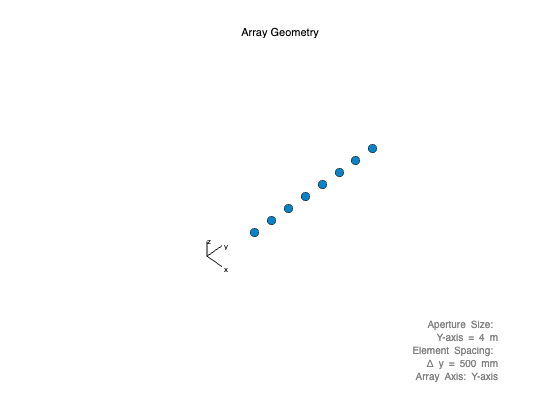

% ULA Specs : 8 Element Uniform Linear Array with Cosine Antenna Element
antenna=phased.ULA;
antenna.NumElements = 8;   
cosineElement = phased.CosineAntennaElement;
antenna.Element = cosineElement;

viewArray(antenna);

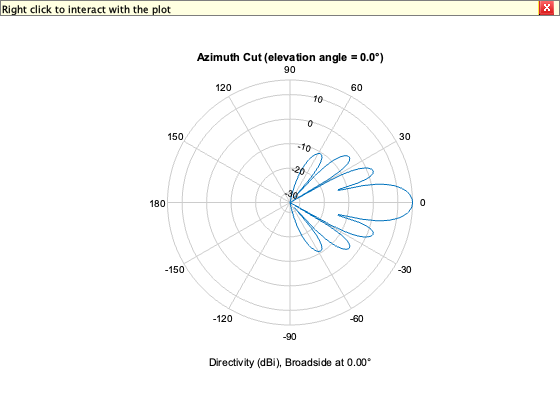

pattern(antenna,300e6,-180:180,0,...
    'Type','directivity',...
    'PropagationSpeed',3e8);

2

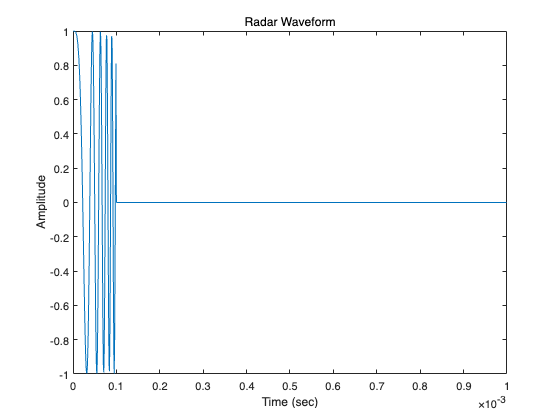

% Waveform Specs
waveform=phased.LinearFMWaveform;
waveform.SampleRate = 1e6;                     % 1 MHz sample rate
waveform.PRF=1000;                             % Pulse Repetition Frequency of 1000 pulses per second
waveform.PulseWidth=1e-4;
nSamples = waveform.SampleRate/waveform.PRF;   % Define pulses on 1000 samples
y = step(waveform);
t = (0:nSamples-1)/waveform.SampleRate;

figure
plot(t,real(y));title('Radar Waveform'); xlabel('Time (sec)'); ylabel('Amplitude')

prf = waveform.PRF;

% Transmitter Specs for amplification
TX=phased.Transmitter('Gain',20);

% Target Specs
TgtModel=phased.RadarTarget;
tgtPos=[10e3*sqrt(3);10e3;0];              % Target at 20 km distance, 30 degree azimuth
tgtVel=[75*sqrt(3);75;0];                  % Radial velocity is 150 m/sec
% Platform Specs
PlatformModel=phased.Platform;
PlatformModel.InitialPosition = tgtPos;
PlatformModel.Velocity = tgtVel;